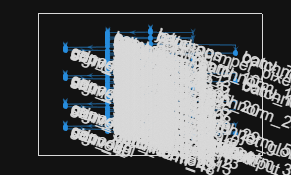

lgraph = layerGraph;

tempNet = [
    imageInputLayer([37 37 12],"Name","jet_props_per_pixel","Normalization","none")
    convolution2dLayer([7 7],48,"Name","conv","Padding","same")
    batchNormalizationLayer("Name","batchnorm")
    reluLayer("Name","relu")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],24,"Name","conv_1")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    groupedConvolution2dLayer([3 3],4,6,"Name","groupedconv","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([1 1],48,"Name","conv_2")
    batchNormalizationLayer("Name","batchnorm_3")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition")
    reluLayer("Name","relu_3")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],24,"Name","conv_3")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    groupedConvolution2dLayer([3 3],4,6,"Name","groupedconv_1","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_5")
    convolution2dLayer([1 1],48,"Name","conv_4")
    batchNormalizationLayer("Name","batchnorm_6")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_1")
    reluLayer("Name","relu_6")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],24,"Name","conv_5")
    batchNormalizationLayer("Name","batchnorm_7")
    reluLayer("Name","relu_7")
    groupedConvolution2dLayer([3 3],4,6,"Name","groupedconv_2","Padding",[1 1 1 1])];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_7")
    batchNormalizationLayer("Name","batchnorm_10")];
lgraph = addLayers(lgraph,tempNet);

tempNet = imageInputLayer([1 1 4],"Name","jet_global_props","Normalization","none");
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    globalAveragePooling2dLayer("Name","gapool_4")
    convolution2dLayer([1 1],3,"Name","conv_34","Padding","same")
    reluLayer("Name","relu_47")
    convolution2dLayer([1 1],24,"Name","conv_35","Padding","same")
    sigmoidLayer("Name","sigmoid_3")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    multiplicationLayer(2,"Name","multiplication_3")
    batchNormalizationLayer("Name","batchnorm_8")
    reluLayer("Name","relu_8")
    convolution2dLayer([1 1],96,"Name","conv_6")
    batchNormalizationLayer("Name","batchnorm_9")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_2")
    reluLayer("Name","relu_9")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],48,"Name","conv_8","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_11")
    reluLayer("Name","relu_10")
    groupedConvolution2dLayer([3 3],6,8,"Name","groupedconv_3","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_12")
    reluLayer("Name","relu_11")
    convolution2dLayer([1 1],96,"Name","conv_9")
    batchNormalizationLayer("Name","batchnorm_13")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_10","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_14")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_3")
    reluLayer("Name","relu_12")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],48,"Name","conv_11")
    batchNormalizationLayer("Name","batchnorm_15")
    reluLayer("Name","relu_13")
    groupedConvolution2dLayer([3 3],6,8,"Name","groupedconv_4","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_16")
    reluLayer("Name","relu_14")
    convolution2dLayer([1 1],96,"Name","conv_12")
    batchNormalizationLayer("Name","batchnorm_17")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_4")
    reluLayer("Name","relu_15")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],48,"Name","conv_13")
    batchNormalizationLayer("Name","batchnorm_18")
    reluLayer("Name","relu_16")
    groupedConvolution2dLayer([3 3],6,8,"Name","groupedconv_5","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_19")
    reluLayer("Name","relu_17")
    convolution2dLayer([1 1],96,"Name","conv_14")
    batchNormalizationLayer("Name","batchnorm_20")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_5")
    reluLayer("Name","relu_18")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],48,"Name","conv_15")
    batchNormalizationLayer("Name","batchnorm_21")
    reluLayer("Name","relu_19")
    groupedConvolution2dLayer([3 3],6,8,"Name","groupedconv_6","Padding",[1 1 1 1])];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],192,"Name","conv_17")
    batchNormalizationLayer("Name","batchnorm_24")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    globalAveragePooling2dLayer("Name","gapool_3")
    convolution2dLayer([1 1],6,"Name","conv_36","Padding","same")
    reluLayer("Name","relu_46")
    convolution2dLayer([1 1],48,"Name","conv_37","Padding","same")
    sigmoidLayer("Name","sigmoid_2")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    multiplicationLayer(2,"Name","multiplication_2")
    batchNormalizationLayer("Name","batchnorm_22")
    reluLayer("Name","relu_20")
    convolution2dLayer([1 1],192,"Name","conv_16")
    batchNormalizationLayer("Name","batchnorm_23")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_6")
    reluLayer("Name","relu_21")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_18","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_25")
    reluLayer("Name","relu_22")
    groupedConvolution2dLayer([3 3],8,12,"Name","groupedconv_7","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_26")
    reluLayer("Name","relu_23")
    convolution2dLayer([1 1],192,"Name","conv_19")
    batchNormalizationLayer("Name","batchnorm_27")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],192,"Name","conv_20","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_28")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_7")
    reluLayer("Name","relu_24")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_21")
    batchNormalizationLayer("Name","batchnorm_29")
    reluLayer("Name","relu_25")
    groupedConvolution2dLayer([3 3],8,12,"Name","groupedconv_8","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_30")
    reluLayer("Name","relu_26")
    convolution2dLayer([1 1],192,"Name","conv_22")
    batchNormalizationLayer("Name","batchnorm_31")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_8")
    reluLayer("Name","relu_27")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_23")
    batchNormalizationLayer("Name","batchnorm_32")
    reluLayer("Name","relu_28")
    groupedConvolution2dLayer([3 3],8,12,"Name","groupedconv_9","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_33")
    reluLayer("Name","relu_29")
    convolution2dLayer([1 1],192,"Name","conv_24")
    batchNormalizationLayer("Name","batchnorm_34")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_9")
    reluLayer("Name","relu_30")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_25")
    batchNormalizationLayer("Name","batchnorm_35")
    reluLayer("Name","relu_31")
    groupedConvolution2dLayer([3 3],8,12,"Name","groupedconv_10","Padding",[1 1 1 1])];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    globalAveragePooling2dLayer("Name","gapool_2")
    convolution2dLayer([1 1],12,"Name","conv_40","Padding","same")
    reluLayer("Name","relu_45")
    convolution2dLayer([1 1],96,"Name","conv_41","Padding","same")
    sigmoidLayer("Name","sigmoid_1")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    multiplicationLayer(2,"Name","multiplication_1")
    batchNormalizationLayer("Name","batchnorm_36")
    reluLayer("Name","relu_32")
    convolution2dLayer([1 1],192,"Name","conv_26")
    batchNormalizationLayer("Name","batchnorm_37")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_10")
    reluLayer("Name","relu_33")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_27","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_40")
    reluLayer("Name","relu_35")
    groupedConvolution2dLayer([3 3],8,12,"Name","groupedconv_11","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_41")
    reluLayer("Name","relu_36")
    convolution2dLayer([1 1],192,"Name","conv_28")
    batchNormalizationLayer("Name","batchnorm_42")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],192,"Name","conv_29","Stride",[2 2])
    batchNormalizationLayer("Name","batchnorm_50")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_11")
    reluLayer("Name","relu_37")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_30")
    batchNormalizationLayer("Name","batchnorm_43")
    reluLayer("Name","relu_38")
    groupedConvolution2dLayer([3 3],8,12,"Name","groupedconv_12","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_44")
    reluLayer("Name","relu_39")
    convolution2dLayer([1 1],192,"Name","conv_31")
    batchNormalizationLayer("Name","batchnorm_45")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_12")
    reluLayer("Name","relu_40")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution2dLayer([1 1],96,"Name","conv_32")
    batchNormalizationLayer("Name","batchnorm_46")
    reluLayer("Name","relu_41")
    groupedConvolution2dLayer([3 3],8,12,"Name","groupedconv_13","Padding",[1 1 1 1])];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    globalAveragePooling2dLayer("Name","gapool_1")
    convolution2dLayer([1 1],8,"Name","conv_38","Padding","same")
    reluLayer("Name","relu_44")
    convolution2dLayer([1 1],96,"Name","conv_39","Padding","same")
    sigmoidLayer("Name","sigmoid")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    multiplicationLayer(2,"Name","multiplication")
    batchNormalizationLayer("Name","batchnorm_47")
    reluLayer("Name","relu_42")
    convolution2dLayer([1 1],192,"Name","conv_33")
    batchNormalizationLayer("Name","batchnorm_48")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition_13")
    reluLayer("Name","relu_43")
    globalAveragePooling2dLayer("Name","gapool")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    depthConcatenationLayer(2,"Name","depthcat")
    fullyConnectedLayer(1000,"Name","fc")
    batchNormalizationLayer("Name","batchnorm_39")
    reluLayer("Name","relu_34")
    dropoutLayer(0.3,"Name","dropout")
    fullyConnectedLayer(2,"Name","fc_1")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempNet);

% clean up helper variable
clear tempNet;


lgraph = connectLayers(lgraph,"relu","conv_1");
lgraph = connectLayers(lgraph,"relu","addition/in1");
lgraph = connectLayers(lgraph,"batchnorm_3","addition/in2");
lgraph = connectLayers(lgraph,"relu_3","conv_3");
lgraph = connectLayers(lgraph,"relu_3","addition_1/in2");
lgraph = connectLayers(lgraph,"batchnorm_6","addition_1/in1");
lgraph = connectLayers(lgraph,"relu_6","conv_5");
lgraph = connectLayers(lgraph,"relu_6","conv_7");
lgraph = connectLayers(lgraph,"groupedconv_2","gapool_4");
lgraph = connectLayers(lgraph,"groupedconv_2","multiplication_3/in1");
lgraph = connectLayers(lgraph,"batchnorm_10","addition_2/in1");
lgraph = connectLayers(lgraph,"jet_global_props","depthcat/in2");
lgraph = connectLayers(lgraph,"sigmoid_3","multiplication_3/in2");
lgraph = connectLayers(lgraph,"batchnorm_9","addition_2/in2");
lgraph = connectLayers(lgraph,"relu_9","conv_8");
lgraph = connectLayers(lgraph,"relu_9","conv_10");
lgraph = connectLayers(lgraph,"batchnorm_13","addition_3/in1");
lgraph = connectLayers(lgraph,"batchnorm_14","addition_3/in2");
lgraph = connectLayers(lgraph,"relu_12","conv_11");
lgraph = connectLayers(lgraph,"relu_12","addition_4/in2");
lgraph = connectLayers(lgraph,"batchnorm_17","addition_4/in1");
lgraph = connectLayers(lgraph,"relu_15","conv_13");
lgraph = connectLayers(lgraph,"relu_15","addition_5/in2");
lgraph = connectLayers(lgraph,"batchnorm_20","addition_5/in1");
lgraph = connectLayers(lgraph,"relu_18","conv_15");
lgraph = connectLayers(lgraph,"relu_18","conv_17");
lgraph = connectLayers(lgraph,"groupedconv_6","gapool_3");
lgraph = connectLayers(lgraph,"groupedconv_6","multiplication_2/in2");
lgraph = connectLayers(lgraph,"batchnorm_24","addition_6/in2");
lgraph = connectLayers(lgraph,"sigmoid_2","multiplication_2/in1");
lgraph = connectLayers(lgraph,"batchnorm_23","addition_6/in1");
lgraph = connectLayers(lgraph,"relu_21","conv_18");
lgraph = connectLayers(lgraph,"relu_21","conv_20");
lgraph = connectLayers(lgraph,"batchnorm_27","addition_7/in1");
lgraph = connectLayers(lgraph,"batchnorm_28","addition_7/in2");
lgraph = connectLayers(lgraph,"relu_24","conv_21");
lgraph = connectLayers(lgraph,"relu_24","addition_8/in2");
lgraph = connectLayers(lgraph,"batchnorm_31","addition_8/in1");
lgraph = connectLayers(lgraph,"relu_27","conv_23");
lgraph = connectLayers(lgraph,"relu_27","addition_9/in2");
lgraph = connectLayers(lgraph,"batchnorm_34","addition_9/in1");
lgraph = connectLayers(lgraph,"relu_30","conv_25");
lgraph = connectLayers(lgraph,"relu_30","addition_10/in2");
lgraph = connectLayers(lgraph,"groupedconv_10","gapool_2");
lgraph = connectLayers(lgraph,"groupedconv_10","multiplication_1/in2");
lgraph = connectLayers(lgraph,"sigmoid_1","multiplication_1/in1");
lgraph = connectLayers(lgraph,"batchnorm_37","addition_10/in1");
lgraph = connectLayers(lgraph,"relu_33","conv_27");
lgraph = connectLayers(lgraph,"relu_33","conv_29");
lgraph = connectLayers(lgraph,"batchnorm_42","addition_11/in1");
lgraph = connectLayers(lgraph,"batchnorm_50","addition_11/in2");
lgraph = connectLayers(lgraph,"relu_37","conv_30");
lgraph = connectLayers(lgraph,"relu_37","addition_12/in2");
lgraph = connectLayers(lgraph,"batchnorm_45","addition_12/in1");
lgraph = connectLayers(lgraph,"relu_40","conv_32");
lgraph = connectLayers(lgraph,"relu_40","addition_13/in2");
lgraph = connectLayers(lgraph,"groupedconv_13","gapool_1");
lgraph = connectLayers(lgraph,"groupedconv_13","multiplication/in2");
lgraph = connectLayers(lgraph,"sigmoid","multiplication/in1");
lgraph = connectLayers(lgraph,"batchnorm_48","addition_13/in1");
lgraph = connectLayers(lgraph,"gapool","depthcat/in1");

analyzeNetwork(lgraph);
plot(lgraph);